# Ejercicio 2 (2 puntos). Transformadas de Laplace en MATLAB.

### **Obtenga la respuesta del sistema, cuyo modelo matemático se expresa a través de la función de transferencia:**

G = 2*tf([1 1], conv([1 0], [1 1 2]));

### Frente a la siguiente entrada:

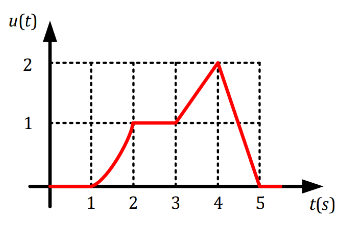

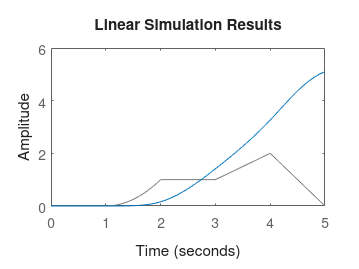

%Creamos las funciones a trozos de cada intervalo.
t = 0:0.1:5;
intervalo1 = 0:0.1:1;
constante1 = 0*intervalo1;

intervalo2 = 1.1:0.1:2;
parabola = intervalo2.^2 - 2*intervalo2 +1;

intervalo3 = 2.1:0.1:3;
constante2 = 0*intervalo3 + 1;

intervalo4 = 3.1:0.1:4;
rampa = intervalo4 - 2;

intervalo5 = 4.1:0.1:5;
rampa2 = -2*intervalo5 + 10;

%Creo el vector entrada para el comando lsim.
entrada = [constante1 parabola constante2 rampa rampa2]; 

%Dibujo la figura con lsim, que da directamente la respuesta
%de la funcion de transferenci G.
figure; hold on
lsim(G,entrada, t); hold off